tifFiles(1) = "\\10.39.168.176\RawData_East3410\190115\190115-1d4Hz-6NBDG.tif";
tifFiles(2) = "\\10.39.168.176\RawData_East3410\190115\190115-1Hz-6NBDG.tif";
tifFiles(3) = "\\10.39.168.176\RawData_East3410\190115\190115-4Hz-6NBDG.tif";

freq = [0.25 1 4];

times = {};
data = {};
normData = {};

for file = 1:numel(tifFiles)
    disp(num2str(file));
    dataFile = readtiff(char(tifFiles(file)));
    
    maxVal = max(dataFile,[],3);
    validIndices = maxVal < 1.5E4;
    
    dataFile = reshape(dataFile,[],size(dataFile,3));
    dataFile = dataFile(validIndices,:);
    dataFile = nanmean(dataFile,1);
    
    time = 1:numel(dataFile); time = time./freq(file);
    
    time(1) = [];
    dataFile(1) = [];
    
    times{file} = time;
    data{file} = dataFile;
    normData{file} = dataFile./max(dataFile);
end

1
2
3


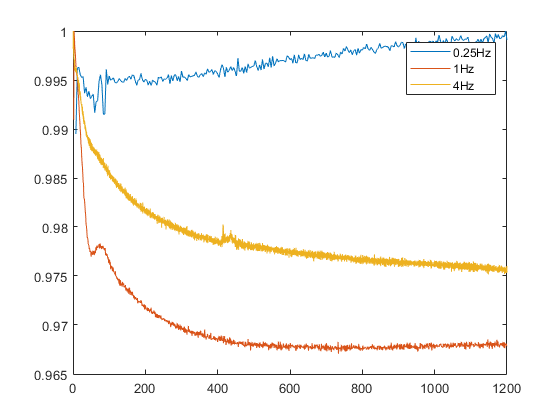

figure;
for file = 1:numel(tifFiles)
    plot(times{file},normData{file});
    hold on;
end
legend('0.25Hz','1Hz','4Hz');

We see that 0.25 Hz pulse with 0.01 second pulse width does not yield any photobleaching.

On the otherhand, 1 and 4 Hz pulses lead to photobleaching.

file = 3;
g = fittype('a*exp(-b*x)+c');
x = times{file}'; y = normData{file}';
f = fit(x,y,g,'StartPoint',[1,0.001,0.98])

f =      General model:
     f(x) = a*exp(-b*x)+c
     Coefficients (with 95% confidence bounds):
       a =      -5.625  (-278, 266.7)
       b =  -2.301e-06  (-0.0001135, 0.0001089)
       c =       6.613  (-265.7, 279)